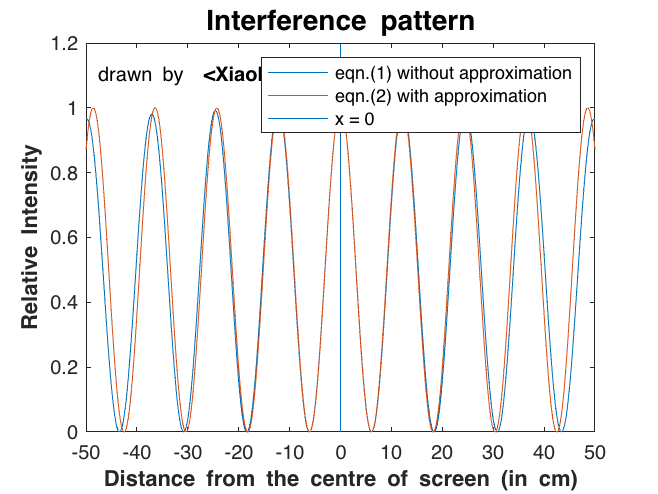

% Script to model the interference between 2 point sources
% separated by a distance d and on a line parallel to a screen
% at a distance D.
% variables names as in Fig. 1 in the lab. script
%
% CHANGE THESE VALUES ACCORDING TO YOUR EXPERIMENTAL SETUP:
d=0.63;             % separation between the sources (in m)
D=2.55;             % distance from sources to screen (in m)
lambda=0.03;        % wavelength (in m)
k=2*pi/lambda;
%
x=-0.5:0.001:0.5;   % to cover 50 cm at either side of the centre
theta1=atan((d/2-x)/D);
theta2=atan((d/2+x)/D);
l1=D./cos(theta1);
l2=D./cos(theta2);
j=0+1i;
Et=exp(-j*k*l1)./l1+exp(-j*k*l2)./l2;
Et=Et.*conj(Et)/(max(Et)^2);
%
Et_approx = 2/(D)*(cos(k*d/2/D*x));
Et_approx=Et_approx.*conj(Et_approx)/(max(Et_approx)^2);


%
y=x*100;            % converting to cm
plot(y,abs(Et));
hold on;
plot(y,Et_approx);
axis([-50 50 0 1.2]);
set(gca,'XTick',-50:10:50)
title('{\bfInterference pattern}','FontSize',14)
xlabel('{\bfDistance from the centre of screen (in cm)}')
ylabel('{\bfRelative Intensity}')
line([0 0],[0 1.2])
legend('eqn.(1) without approximation', 'eqn.(2) with approximation','x = 0')
hold off;
% line([-0.5 0.5],[1 1],'linestyle',':')
 text(-48, 1.1,'drawn by {\bf <Xiaokun> }')